## Test function: Chained Powel singular function - 10^3

% Dimension n (multiple of 4)
n = 10^3;  % 10^3;

% Initializations
f = @(x) 0;
x0 = zeros(n, 1);

% Chained Powel singular function
for j = 1 : (n - 2)/2
    f_1 = @(x) ((x(2*j-1, :) + 10*x(2*j, :)).^2 + ...
        5*(x(2*j+1, :) - x(2*j+2, :)).^2 + ...
        (x(2*j, :).^2 - 2*x(2*j+1, :)).^4 + ...
        10*(x(2*j-1, :) - x(2*j+2, :)).^4);  % Powel singular function (j=1)
    f = @(x) f(x) + f_1(x);  % Chained Powel singular function
end

% f = @(x) chainedpowell(x);

% Starting point x0
for j = 1 : n
    if mod(j, 4) == 0
        x0(j) = 1;
    elseif mod(j, 4) == 1
        x0(j) = 3;
    elseif mod(j, 4) == 2
        x0(j) = -1;
    else
        x0(j) = 0;
    end
end

% Expected solution
x_sol = zeros(1, n)';

% Gradient
gradf = @(x) chainedpowell_grad(x);

### Parameters 

load('forcing_terms.mat')

kmax = 1000;  % maximum number of iterations
step_k = 5;  % step between one iteration and the successive to memorize efficiently the orders fo convergence and the errors;
tolgrad = 1e-8;  % stopping criterion w.r.t. the norm of the gradient
alpha0 = 10;  % initial step-length
c1 = 1e-1;  % factor of the Armijo condition
rho = 0.5;  % fixed factor used for reducing alpha0
btmax = 500;  % ﻿maximum number of steps for updating alpha
parameters = table(kmax, step_k, tolgrad, alpha0, c1, rho, btmax)

parameters = 1×7 table
    kmax    step_k    tolgrad    alpha0    c1     rho    btmax
    ____    ______    _______    ______    ___    ___    _____

    1000      5        1e-08       10      0.1    0.5     500 


## Steepest descent method - 10^3

[xk, fk, gradfk_norm, k, big_k, err_fseq, ordconv_seq, totalTimeCost, timeCostseq] = ...
    steepest_desc_bckt(x0, x_sol, f, gradf, alpha0, step_k, kmax, tolgrad, c1, rho, btmax);

*** Iterations overcome maximum number of iterations ***

results_0 = table(xk, x_sol);
head(results_0, 8)

ans = 8×2 table
        xk         x_sol
    ___________    _____

       0.014113      0  
     -0.0014113      0  
    -6.5007e-07      0  
    -3.0663e-06      0  
     8.7562e-13      0  
     1.7381e-11      0  
    -3.3599e-13      0  
    -6.6694e-12      0  


tail(results_0, 8)

ans = 8×2 table
        xk         x_sol
    ___________    _____

    -1.2104e-13      0  
    -2.4028e-12      0  
     1.2969e-12      0  
     2.5744e-11      0  
     6.2651e-06      0  
    -3.4453e-09      0  
       0.012333      0  
       0.012351      0  


gradfk_norm_x0 = norm(gradf(x0));
gradfk_norm_inf = norm(gradf(xk), "inf");
errf_final = err_fseq(end);
results_1 = table(fk, k, gradfk_norm_x0, gradfk_norm, gradfk_norm_inf, errf_final, totalTimeCost)

results_1 = 1×7 table
        fk         k      gradfk_norm_x0    gradfk_norm    gradfk_norm_inf    errf_final    totalTimeCost
    __________    ____    ______________    ___________    _______________    __________    _____________

    1.0024e-06    1000        7342.1        0.00081561       0.00076293       1.0024e-06       2.1625    


err_fseq = err_fseq';
ordconv_seq = ordconv_seq';
timeCostseq = timeCostseq';
results_2 = table(err_fseq, ordconv_seq, timeCostseq);
head(results_2, 8)

ans = 8×3 table
    err_fseq     ordconv_seq    timeCostseq
    _________    ___________    ___________

       96.891      0.27216       0.045764  
       2.4508     0.098212       0.059199  
       0.2124       14.249       0.076385  
     0.030009      0.12117       0.086366  
    0.0087814       1.0171       0.095487  
    0.0028451      0.44513        0.10469  
    0.0013705       48.315         0.1135  
    0.0006428       1.5044         0.1234  


tail(results_2, 8)

ans = 8×3 table
     err_fseq     ordconv_seq    timeCostseq
    __________    ___________    ___________

    1.0829e-06      0.73186        2.0839   
    1.0547e-06       11.036        2.0953   
    1.0483e-06      0.57202        2.1057   
    1.0421e-06       1.7175        2.1153   
    1.0345e-06       1.1666        2.1283   
    1.0299e-06        1.897        2.1411   
    1.0182e-06        49.07        2.1514   
    1.0024e-06     0.079229        2.1625   


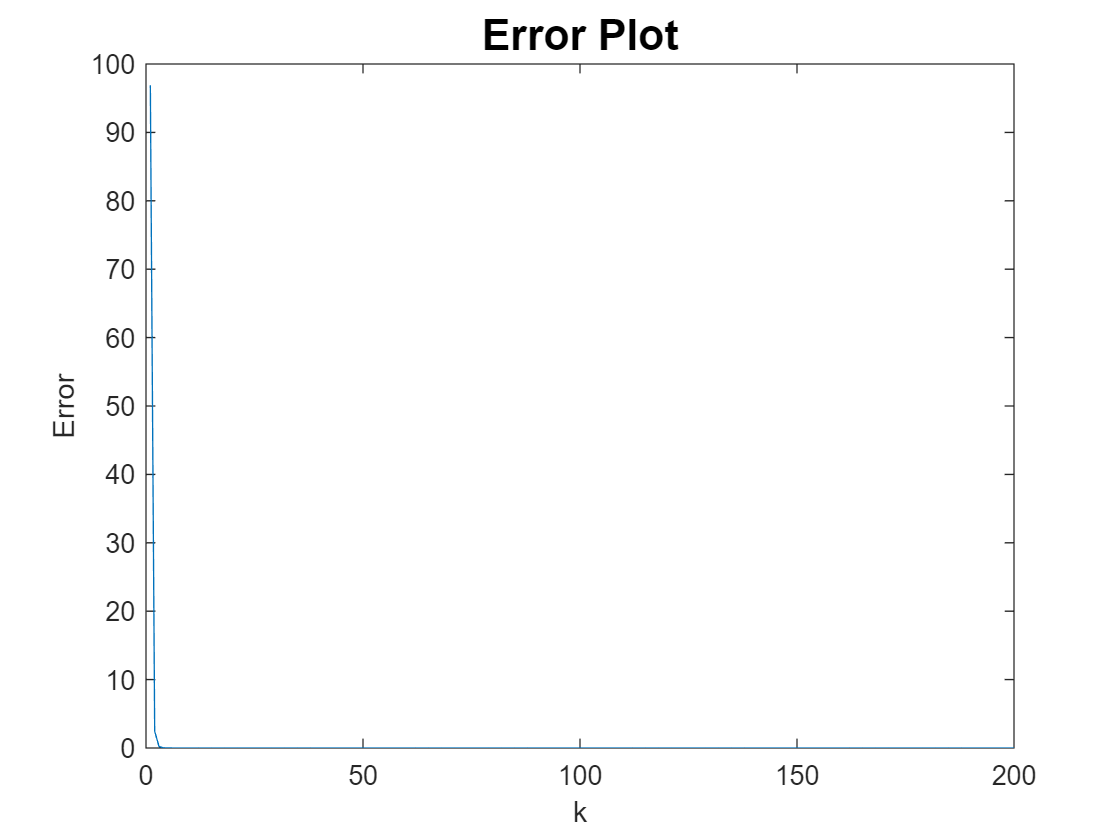

plot(1:big_k, err_fseq)
title('Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

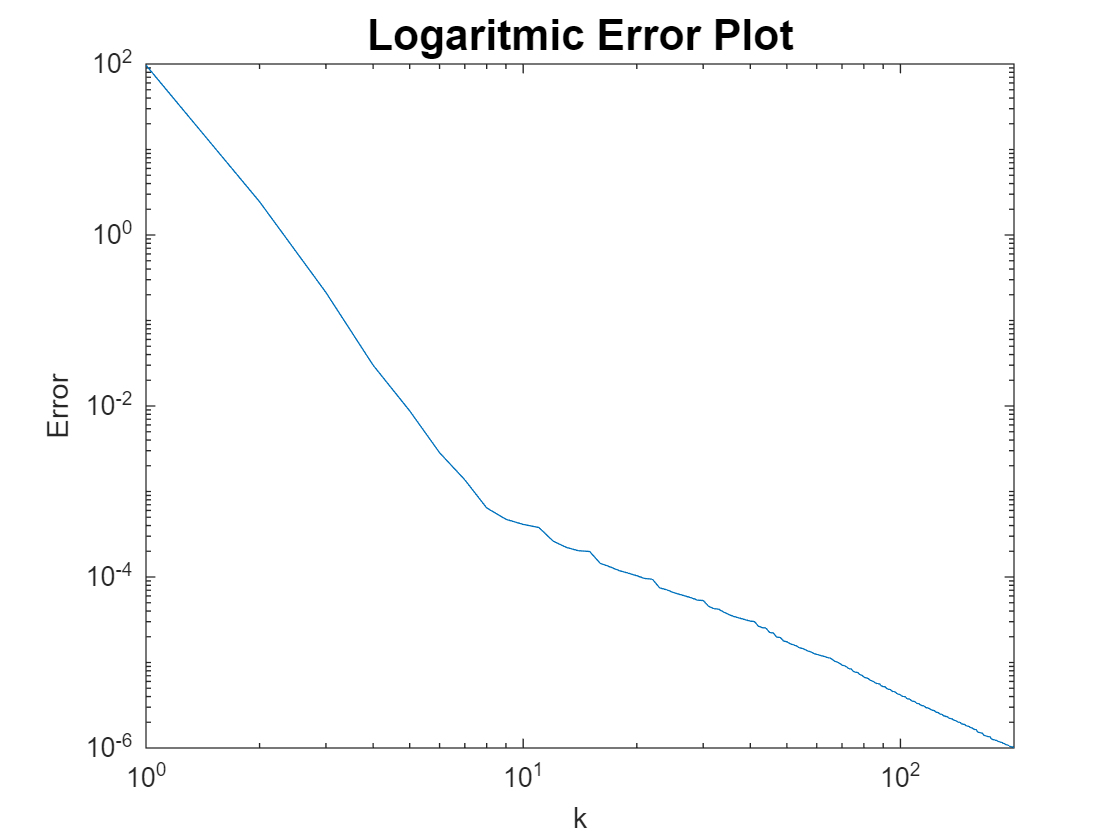

loglog(1:big_k, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

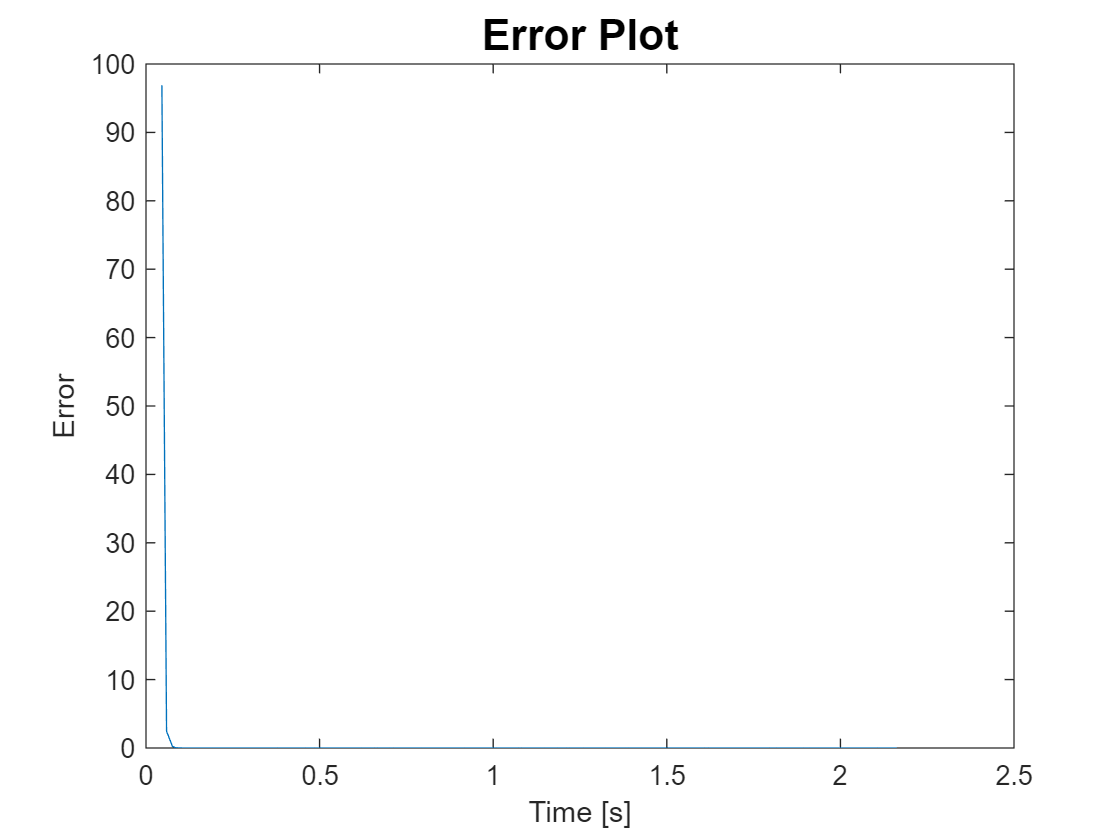

plot(timeCostseq, err_fseq)
title('Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

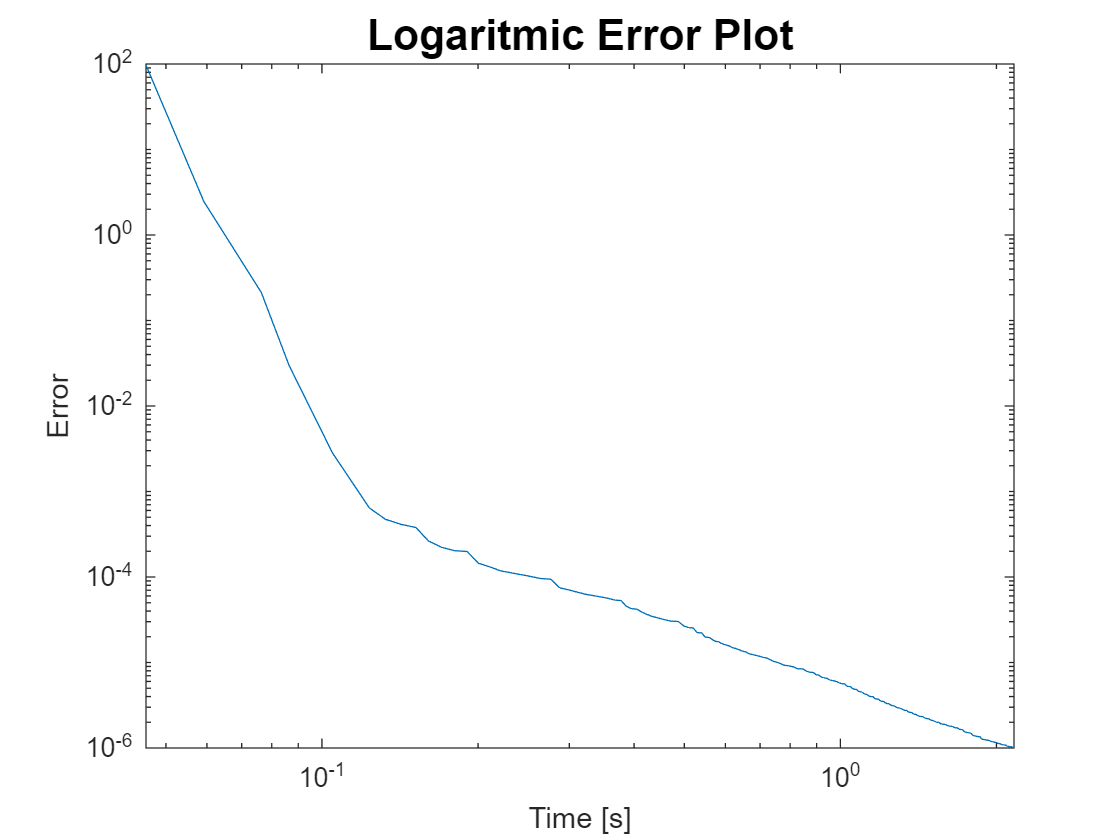

loglog(timeCostseq, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

## Inexact Newton method - 10^3

### Parameters

kmax = 100;  % maximum number of iterations
step_k = 5;  % step between one iteration and the successive to memorize efficiently the orders fo convergence and the errors;
tolgrad = 1e-8;  % stopping criterion w.r.t. the norm of the gradient
c1 = 1e-4;  % factor of the Armijo condition
rho = 0.5;  % fixed factor used for reducing alpha0
btmax = 500;  % ﻿maximum number of steps for updating alpha
parameters = table(kmax, step_k, tolgrad, alpha0, c1, rho, btmax)

parameters = 1×7 table
    kmax    step_k    tolgrad    alpha0      c1      rho    btmax
    ____    ______    _______    ______    ______    ___    _____

    100       5        1e-08       10      0.0001    0.5     500 


% gradf = @(x) 0;
Hessf = @(x) 0;
FDgrad = 1;  % 'otherwise' case of "findiff_grad"
FDHess = 'Jc';
h = sqrt(eps);
fterms = fterms_lin;
pcg_maxit = 50;  % 100
[xk, fk, gradfk_norm, k, big_k, pk_itcount, err_fseq, ordconv_seq, totalTimeCost, timeCostseq] = ...
    innewton_bcktrck(x0, x_sol, f, gradf, Hessf, step_k, kmax, ...
    tolgrad, c1, rho, btmax, FDgrad, FDHess, h, fterms, pcg_maxit);

*** Iterations overcome maximum number of iterations ***

results_0 = table(xk, x_sol);
head(results_0, 8)

ans = 8×2 table
        xk         x_sol
    ___________    _____

      0.0014377      0  
    -0.00014377      0  
    -3.4546e-10      0  
      1.738e-11      0  
    -1.3086e-12      0  
     6.5921e-14      0  
     1.0161e-12      0  
    -5.1187e-14      0  


tail(results_0, 8)

ans = 8×2 table
        xk         x_sol
    ___________    _____

     -1.229e-12      0  
     6.1913e-14      0  
     1.0631e-12      0  
    -5.3555e-14      0  
    -1.9886e-11      0  
     1.0679e-12      0  
      0.0012547      0  
      0.0012547      0  


gradfk_norm_x0 = norm(gradf(x0));
gradfk_norm_inf = norm(gradf(xk), "inf");
errf_final = err_fseq(end);
results_1 = table(fk, k, pk_itcount, gradfk_norm_x0, gradfk_norm, gradfk_norm_inf, errf_final, totalTimeCost)

results_1 = 1×8 table
        fk         k     pk_itcount    gradfk_norm_x0    gradfk_norm    gradfk_norm_inf    errf_final    totalTimeCost
    __________    ___    __________    ______________    ___________    _______________    __________    _____________

    1.0717e-10    100       558            7342.1        2.4644e-07       1.2642e-07       1.0717e-10       1.7711    


err_fseq = err_fseq';
ordconv_seq = ordconv_seq';
timeCostseq = timeCostseq';
results_2 = table(err_fseq, ordconv_seq, timeCostseq);
head(results_2, 8)

ans = 8×3 table
     err_fseq     ordconv_seq    timeCostseq
    __________    ___________    ___________

        24.465       2.4266       0.046488  
      0.023877       1.4618        0.08639  
    9.1333e-06       0.9993        0.12718  
    2.7467e-09      0.99999        0.16699  
    1.0717e-10          NaN        0.24037  
    1.0717e-10          NaN        0.32761  
    1.0717e-10          NaN        0.45239  
    1.0717e-10          NaN        0.56547  


tail(results_2, 8)

ans = 8×3 table
     err_fseq     ordconv_seq    timeCostseq
    __________    ___________    ___________

    1.0717e-10        NaN          1.0691   
    1.0717e-10        NaN          1.1736   
    1.0717e-10        NaN          1.2679   
    1.0717e-10        NaN          1.3685   
    1.0717e-10        NaN          1.4693   
    1.0717e-10        NaN          1.5733   
    1.0717e-10        NaN          1.6704   
    1.0717e-10        NaN          1.7711   


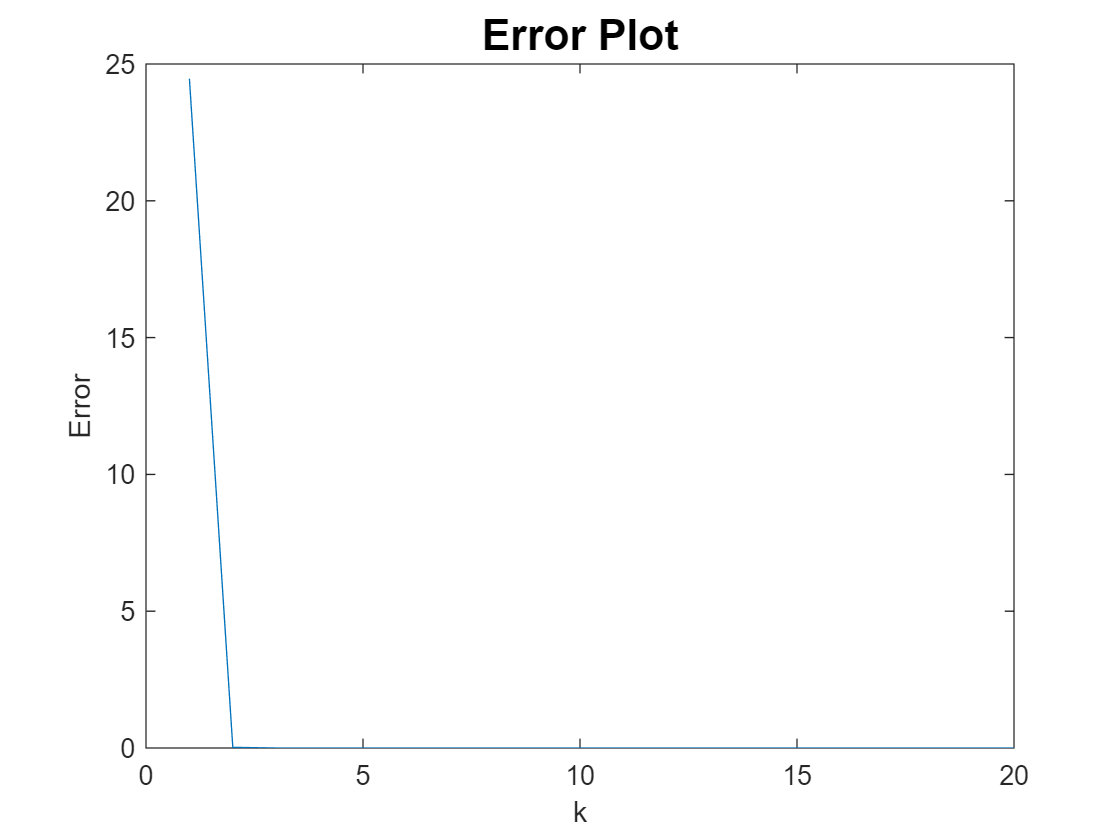

plot(1:big_k, err_fseq)
title('Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

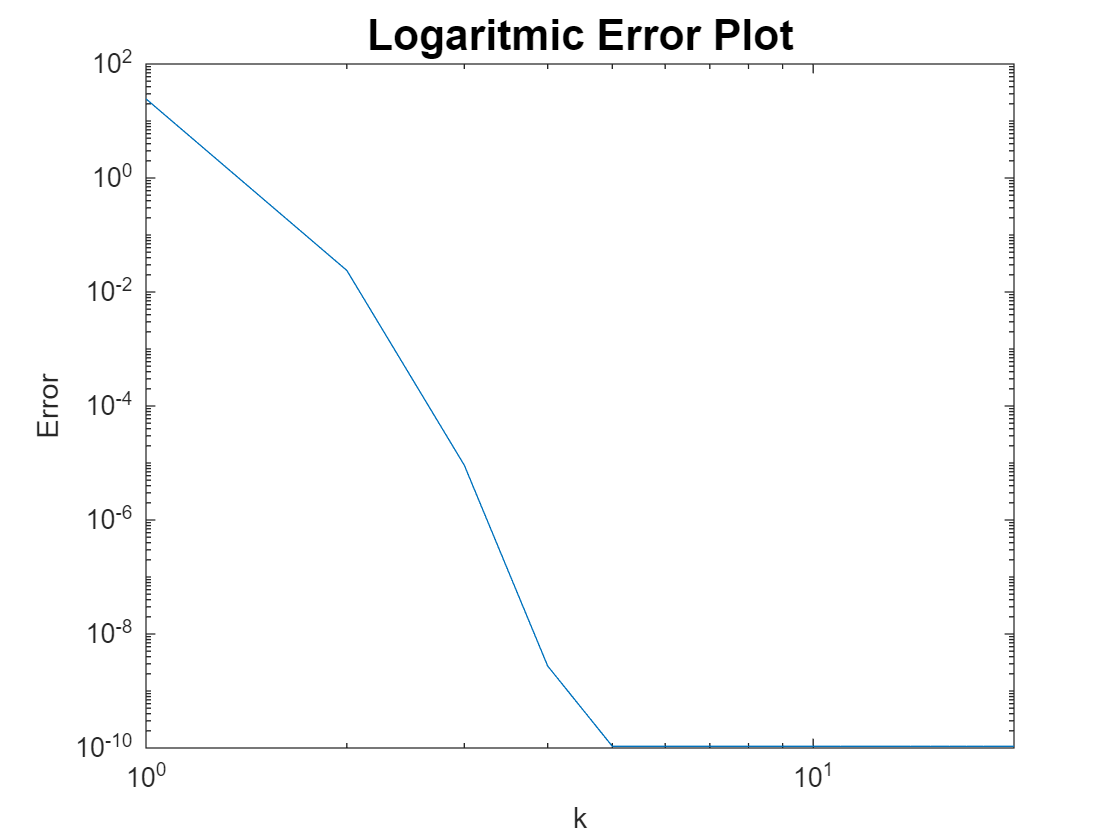

loglog(1:big_k, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

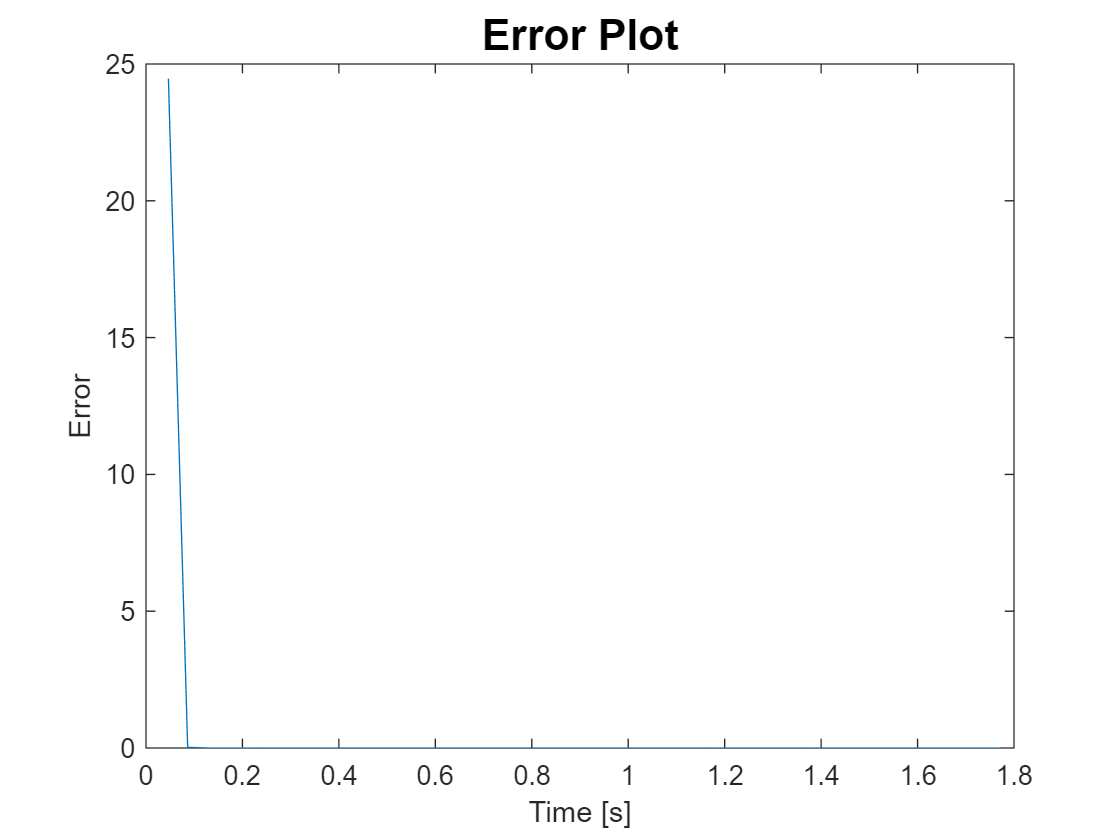

plot(timeCostseq, err_fseq)
title('Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

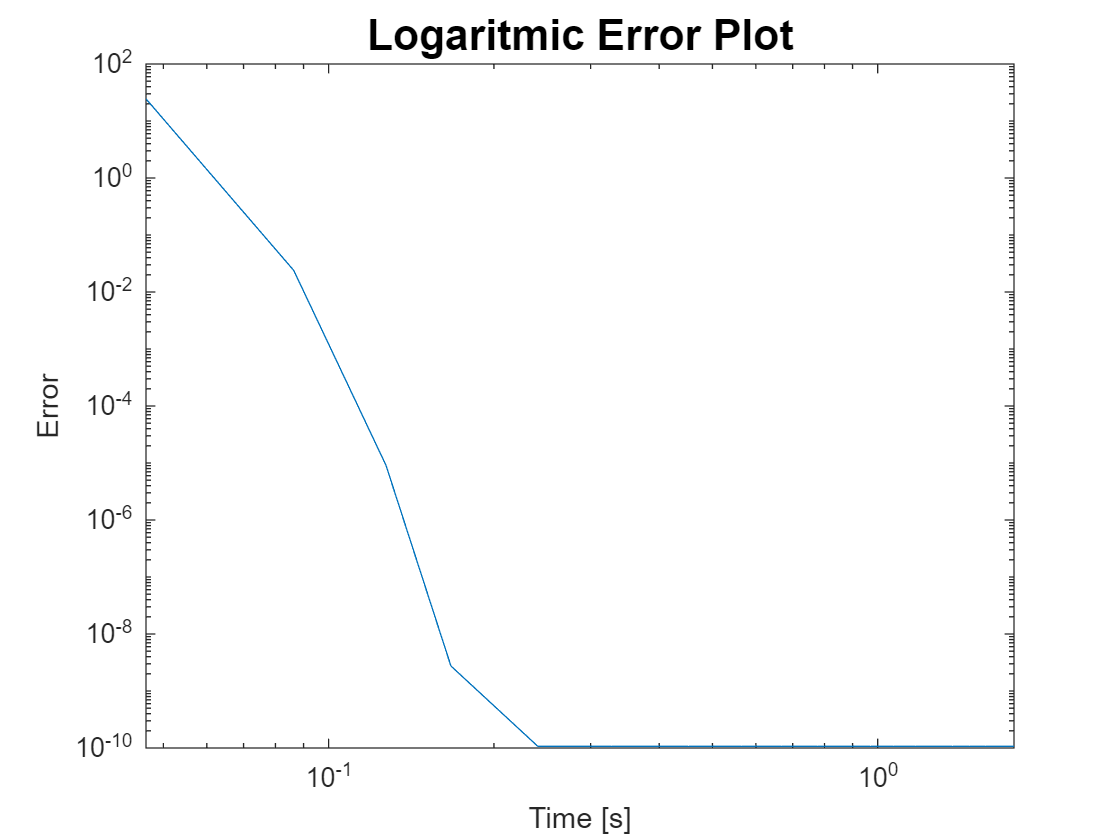

loglog(timeCostseq, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

## Modified Newton method - 10^3

### Parameters

kmax = 500;  % maximum number of iterations
step_k = 5;  % step between one iteration and the successive to memorize efficiently the orders fo convergence and the errors;
tolgrad = 1e-14;  % stopping criterion w.r.t. the norm of the gradient
c1 = 1e-4;  % factor of the Armijo condition
rho = 0.5;  % fixed factor used for reducing alpha0
btmax = 500;  % ﻿maximum number of steps for updating alpha
parameters = table(kmax, step_k, tolgrad, c1, rho, btmax)

parameters = 1×6 table
    kmax    step_k    tolgrad      c1      rho    btmax
    ____    ______    _______    ______    ___    _____

    500       5        1e-14     0.0001    0.5     500 


Hessf = @(x) 0;
FDgrad = 1;  % 'otherwise' case of "findiff_grad"
FDHess = 'Jc';
h = sqrt(eps)*norm(x0);
[xk, fk, gradfk_norm, k, big_k, err_fseq, ordconv_seq, ...
    totalTimeCost, timeCostseq] = modnewton_bcktrck(x0,x_sol,f,gradf,...
    Hessf,step_k,kmax,tolgrad,c1,rho,btmax, FDgrad, FDHess, h);

*** Tolerance is not respected ***

results_0 = table(xk, x_sol);
head(results_0, 8)

ans = 8×2 table
        xk         x_sol
    ___________    _____

     4.8633e-06      0  
    -4.8633e-07      0  
     5.3691e-21      0  
    -2.4136e-22      0  
     1.7039e-35      0  
    -1.7295e-35      0  
     2.3776e-49      0  
    -6.3049e-50      0  


tail(results_0, 8)

ans = 8×2 table
        xk         x_sol
    ___________    _____

    -2.7155e-49      0  
     2.3024e-50      0  
     5.0776e-37      0  
     -5.804e-37      0  
    -6.7353e-23      0  
     1.3337e-25      0  
    -3.5262e-06      0  
    -3.5262e-06      0  


gradfk_norm_x0 = norm(gradf(x0));
gradfk_norm_inf = norm(gradf(xk), "inf");
errf_final = err_fseq(end);
results_1 = table(fk, k, gradfk_norm_x0, gradfk_norm, gradfk_norm_inf, errf_final, totalTimeCost)

results_1 = 1×7 table
        fk        k     gradfk_norm_x0    gradfk_norm    gradfk_norm_inf    errf_final    totalTimeCost
    __________    __    ______________    ___________    _______________    __________    _____________

    9.6138e-21    55        7342.1        7.6376e-15       4.6011e-15       9.6138e-21       0.92356   


err_fseq = err_fseq';
ordconv_seq = ordconv_seq';
timeCostseq = timeCostseq';
results_2 = table(err_fseq, ordconv_seq, timeCostseq);
head(results_2, 8)

ans = 8×3 table
     err_fseq     ordconv_seq    timeCostseq
    __________    ___________    ___________

        134.28       1.2904        0.14049  
       0.93317        1.336        0.23745  
    0.00017731      0.95592         0.3273  
     1.643e-06      0.99975        0.41623  
    1.5217e-08            1        0.50075  
    1.4093e-10            1        0.57163  
    1.3053e-12            1        0.64158  
    1.2089e-14            1        0.70986  


tail(results_2, 8)

ans = 8×3 table
     err_fseq     ordconv_seq    timeCostseq
    __________    ___________    ___________

     1.643e-06      0.99975        0.41623  
    1.5217e-08            1        0.50075  
    1.4093e-10            1        0.57163  
    1.3053e-12            1        0.64158  
    1.2089e-14            1        0.70986  
    1.1197e-16            1        0.77981  
    1.0371e-18      0.99998        0.85219  
    9.6138e-21      0.99984        0.92356  


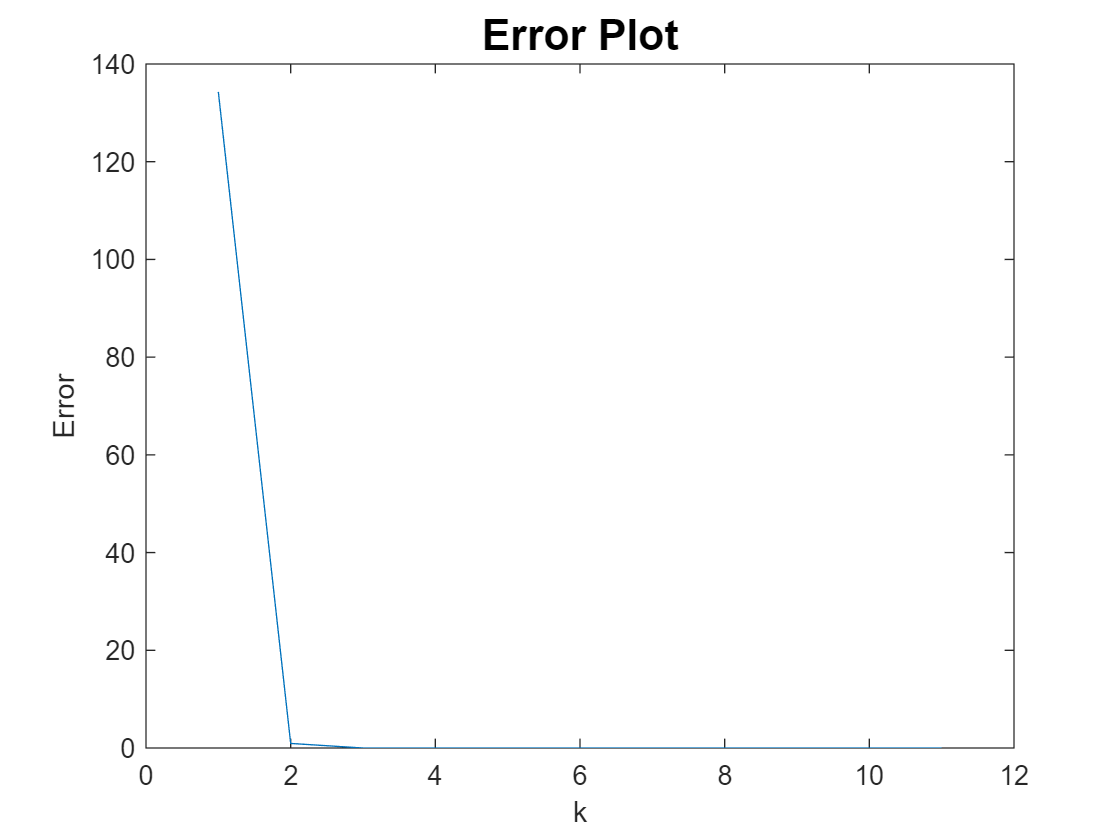

plot(1:big_k, err_fseq)
title('Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

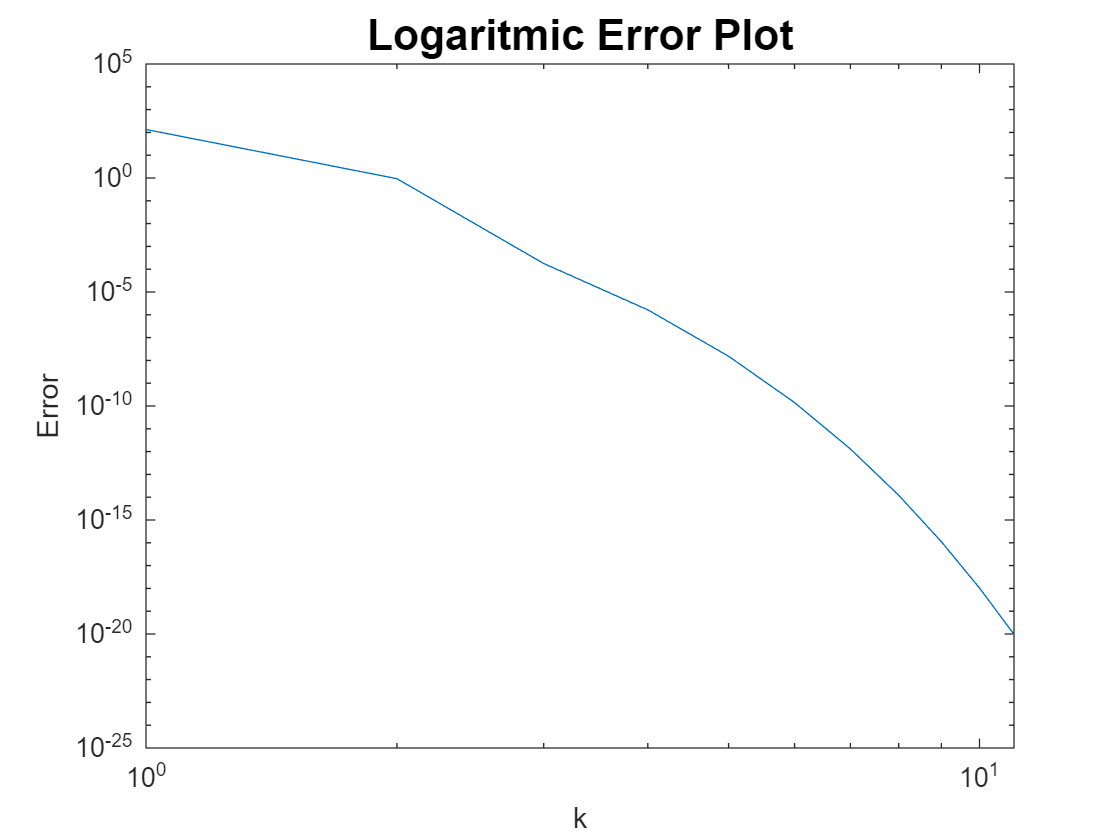

loglog(1:big_k, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

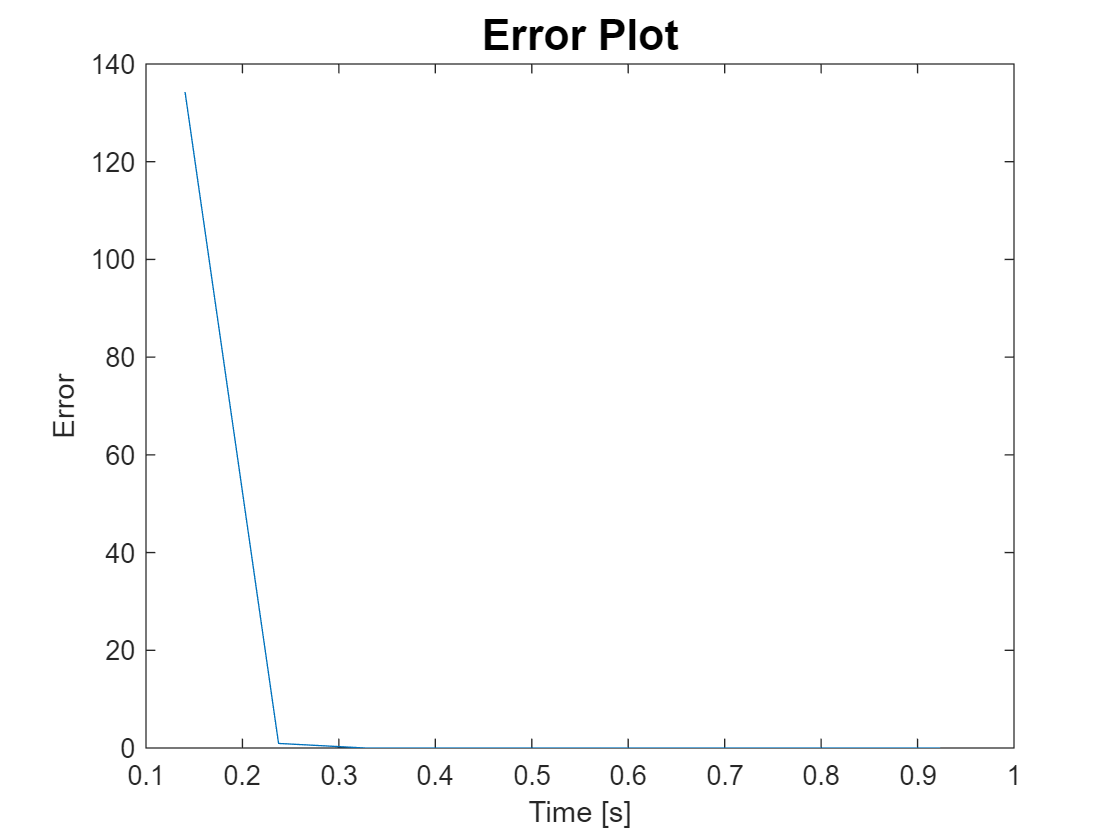

plot(timeCostseq, err_fseq)
title('Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

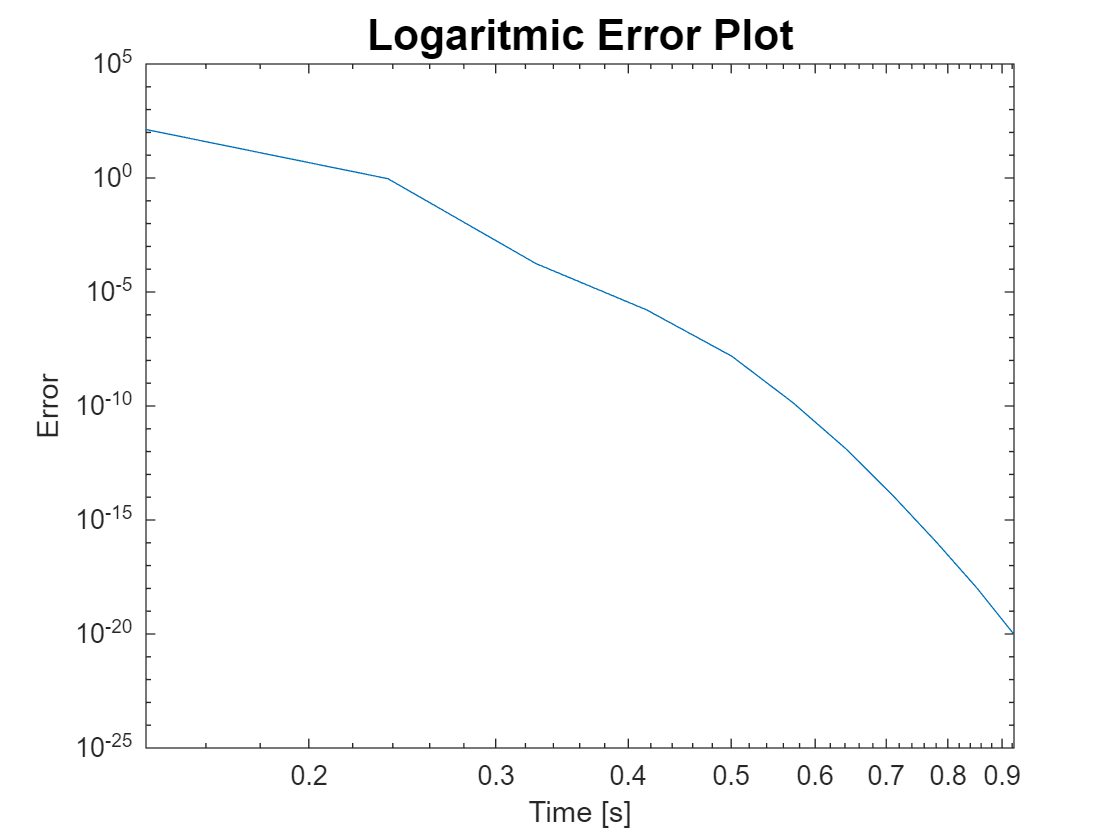

loglog(timeCostseq, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

## Test function: Chained Powel singular function - 10^4

% Dimension n (multiple of 4)
n = 10^4;  % 10^4;

% Initializations
f = @(x) 0;
x0 = zeros(n, 1);

% Chained Powel singular function
for j = 1 : (n - 2)/2
    f_1 = @(x) ((x(2*j-1, :) + 10*x(2*j, :)).^2 + ...
        5*(x(2*j+1, :) - x(2*j+2, :)).^2 + ...
        (x(2*j, :).^2 - 2*x(2*j+1, :)).^4 + ...
        10*(x(2*j-1, :) - x(2*j+2, :)).^4);  % Powel singular function (j=1)
    f = @(x) f(x) + f_1(x);  % Chained Powel singular function
end

% Starting point x0
for j = 1 : n
    if mod(j, 4) == 0
        x0(j) = 1;
    elseif mod(j, 4) == 1
        x0(j) = 3;
    elseif mod(j, 4) == 2
        x0(j) = -1;
    else
        x0(j) = 0;
    end
end

% Expected solution
x_sol = zeros(1, n)';

% Gradient
gradf = @(x) chainedpowell_grad(x);

### Parameters 

load('forcing_terms.mat')

kmax = 1000;  % maximum number of iterations
step_k = 5;  % step between one iteration and the successive to memorize efficiently the orders fo convergence and the errors;
tolgrad = 1e-8;  % stopping criterion w.r.t. the norm of the gradient
alpha0 = 10;  % initial step-length
c1 = 1e-1;  % factor of the Armijo condition
rho = 0.5;  % fixed factor used for reducing alpha0
btmax = 500;  % ﻿maximum number of steps for updating alpha
parameters = table(kmax, step_k, tolgrad, alpha0, c1, rho, btmax)

parameters = 1×7 table
    kmax    step_k    tolgrad    alpha0    c1     rho    btmax
    ____    ______    _______    ______    ___    ___    _____

    1000      5        1e-08       10      0.1    0.5     500 


## Steepest descent method - 10^4

[xk, fk, gradfk_norm, k, big_k, err_fseq, ordconv_seq, totalTimeCost, timeCostseq] = ...
    steepest_desc_bckt(x0, x_sol, f, gradf, alpha0, step_k, kmax, tolgrad, c1, rho, btmax);

*** Iterations overcome maximum number of iterations ***

results_0 = table(xk, x_sol);
head(results_0, 8)

ans = 8×2 table
        xk         x_sol
    ___________    _____

       0.014113      0  
     -0.0014113      0  
    -6.5007e-07      0  
    -3.0663e-06      0  
     8.7562e-13      0  
     1.7381e-11      0  
    -3.3599e-13      0  
    -6.6694e-12      0  


tail(results_0, 8)

ans = 8×2 table
        xk         x_sol
    ___________    _____

    -1.2104e-13      0  
    -2.4028e-12      0  
     1.2969e-12      0  
     2.5744e-11      0  
     6.2651e-06      0  
    -3.4453e-09      0  
       0.012333      0  
       0.012351      0  


gradfk_norm_x0 = norm(gradf(x0));
gradfk_norm_inf = norm(gradf(xk), "inf");
errf_final = err_fseq(end);
results_1 = table(fk, k, gradfk_norm_x0, gradfk_norm, gradfk_norm_inf, errf_final, totalTimeCost)

results_1 = 1×7 table
        fk         k      gradfk_norm_x0    gradfk_norm    gradfk_norm_inf    errf_final    totalTimeCost
    __________    ____    ______________    ___________    _______________    __________    _____________

    1.0024e-06    1000        7342.1        0.00081561       0.00076293       1.0024e-06        2.313    


err_fseq = err_fseq';
ordconv_seq = ordconv_seq';
timeCostseq = timeCostseq';
results_2 = table(err_fseq, ordconv_seq, timeCostseq);
head(results_2, 8)

ans = 8×3 table
    err_fseq     ordconv_seq    timeCostseq
    _________    ___________    ___________

       96.891      0.27216       0.041975  
       2.4508     0.098212       0.056226  
       0.2124       14.249       0.072966  
     0.030009      0.12117       0.084526  
    0.0087814       1.0171       0.092981  
    0.0028451      0.44513        0.10217  
    0.0013705       48.315        0.11031  
    0.0006428       1.5044        0.12038  


tail(results_2, 8)

ans = 8×3 table
     err_fseq     ordconv_seq    timeCostseq
    __________    ___________    ___________

    1.0829e-06      0.73186        2.2372   
    1.0547e-06       11.036        2.2454   
    1.0483e-06      0.57202        2.2549   
    1.0421e-06       1.7175        2.2639   
    1.0345e-06       1.1666         2.273   
    1.0299e-06        1.897        2.2823   
    1.0182e-06        49.07        2.2977   
    1.0024e-06     0.079229         2.313   


plot(1:big_k, err_fseq)
title('Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

loglog(1:big_k, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

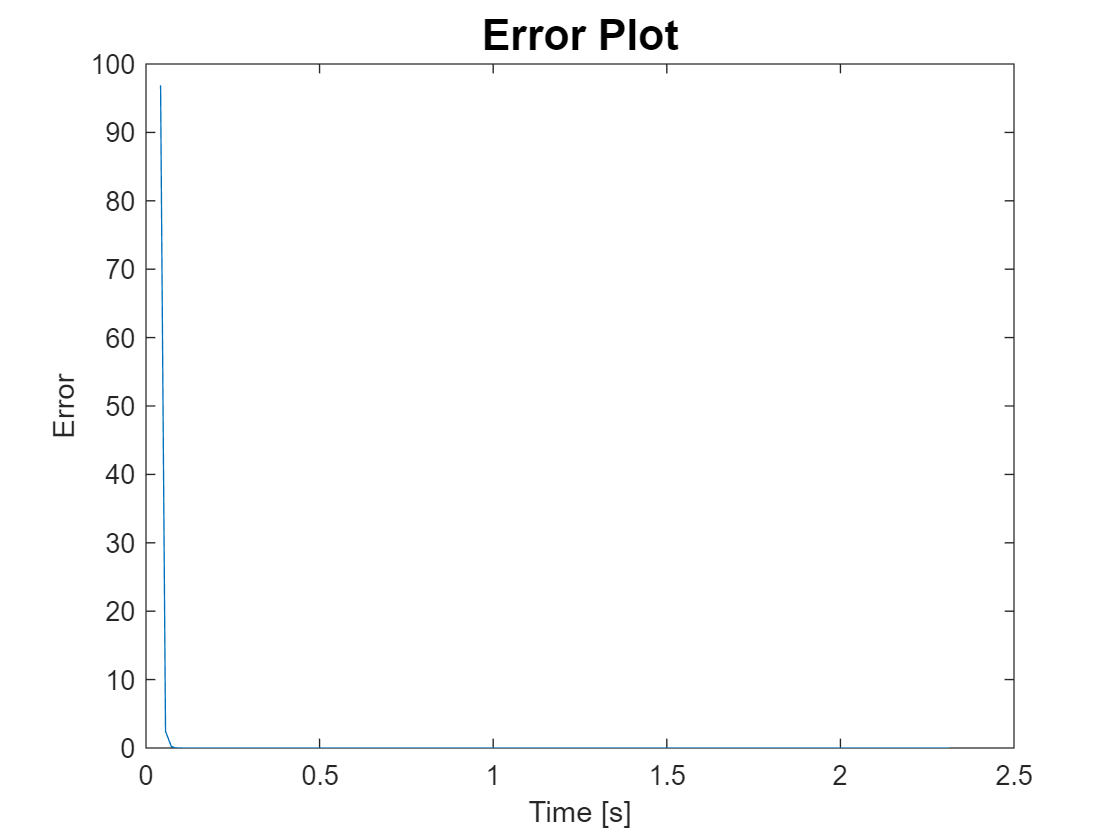

plot(timeCostseq, err_fseq)
title('Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

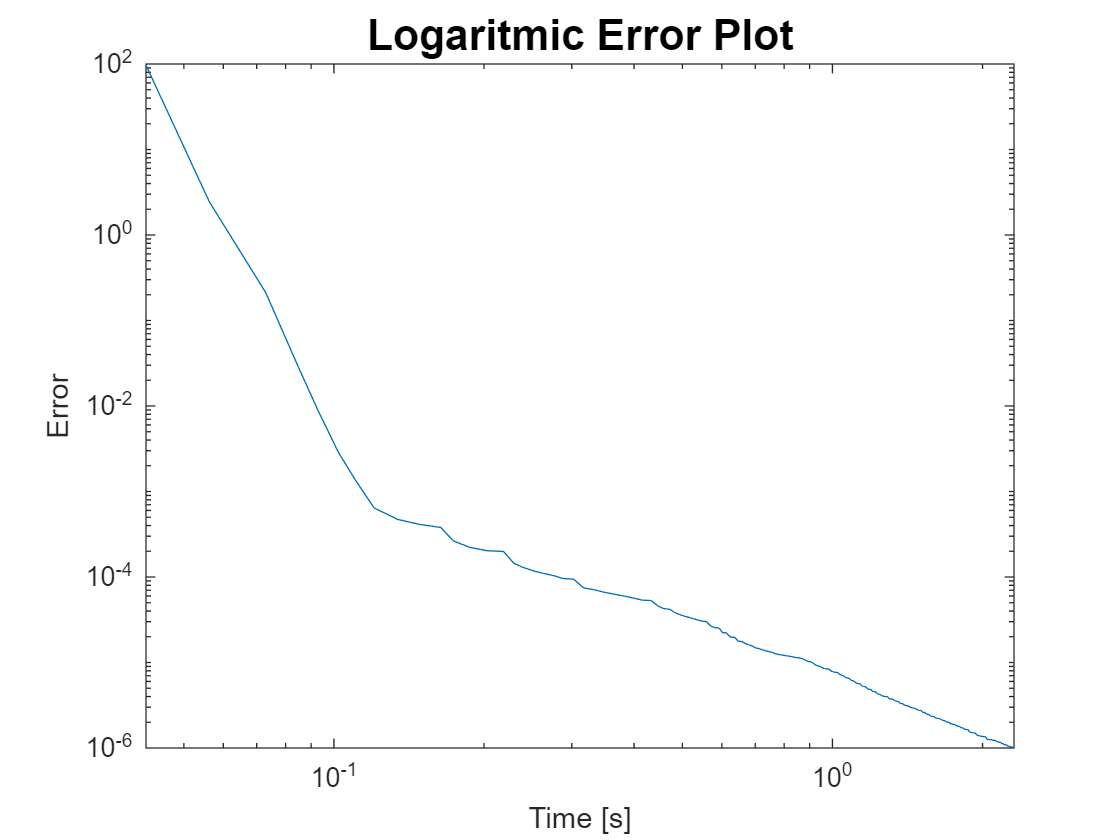

loglog(timeCostseq, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

## Inexact Newton method - 10^4

### Parameters

kmax = 100;  % maximum number of iterations
step_k = 5;  % step between one iteration and the successive to memorize efficiently the orders fo convergence and the errors;
tolgrad = 1e-8;  % stopping criterion w.r.t. the norm of the gradient
c1 = 1e-4;  % factor of the Armijo condition
rho = 0.5;  % fixed factor used for reducing alpha0
btmax = 500;  % ﻿maximum number of steps for updating alpha
parameters = table(kmax, step_k, tolgrad, alpha0, c1, rho, btmax)

parameters = 1×7 table
    kmax    step_k    tolgrad    alpha0      c1      rho    btmax
    ____    ______    _______    ______    ______    ___    _____

    100       5        1e-08       10      0.0001    0.5     500 


% gradf = @(x) 0;
Hessf = @(x) 0;
FDgrad = 1;  % 'otherwise' case of "findiff_grad"
FDHess = 'Jc';
h = sqrt(eps);
fterms = fterms_lin;
pcg_maxit = 50;  % 100
[xk, fk, gradfk_norm, k, big_k, pk_itcount, err_fseq, ordconv_seq, totalTimeCost, timeCostseq] = ...
    innewton_bcktrck(x0, x_sol, f, gradf, Hessf, step_k, kmax, ...
    tolgrad, c1, rho, btmax, FDgrad, FDHess, h, fterms, pcg_maxit);

*** Iterations overcome maximum number of iterations ***

results_0 = table(xk, x_sol);
head(results_0, 8)

ans = 8×2 table
        xk         x_sol
    ___________    _____

      0.0014377      0  
    -0.00014377      0  
    -3.4546e-10      0  
      1.738e-11      0  
    -1.3086e-12      0  
     6.5921e-14      0  
     1.0161e-12      0  
    -5.1187e-14      0  


tail(results_0, 8)

ans = 8×2 table
        xk         x_sol
    ___________    _____

     -1.229e-12      0  
     6.1913e-14      0  
     1.0631e-12      0  
    -5.3555e-14      0  
    -1.9886e-11      0  
     1.0679e-12      0  
      0.0012547      0  
      0.0012547      0  


gradfk_norm_x0 = norm(gradf(x0));
gradfk_norm_inf = norm(gradf(xk), "inf");
errf_final = err_fseq(end);
results_1 = table(fk, k, pk_itcount, gradfk_norm_x0, gradfk_norm, gradfk_norm_inf, errf_final, totalTimeCost)

results_1 = 1×8 table
        fk         k     pk_itcount    gradfk_norm_x0    gradfk_norm    gradfk_norm_inf    errf_final    totalTimeCost
    __________    ___    __________    ______________    ___________    _______________    __________    _____________

    1.0717e-10    100       558            7342.1        2.4644e-07       1.2642e-07       1.0717e-10       1.6843    


err_fseq = err_fseq';
ordconv_seq = ordconv_seq';
timeCostseq = timeCostseq';
results_2 = table(err_fseq, ordconv_seq, timeCostseq);
head(results_2, 8)

ans = 8×3 table
     err_fseq     ordconv_seq    timeCostseq
    __________    ___________    ___________

        24.465       2.4266       0.043009  
      0.023877       1.4618       0.084486  
    9.1333e-06       0.9993        0.12583  
    2.7467e-09      0.99999        0.16919  
    1.0717e-10          NaN        0.24195  
    1.0717e-10          NaN        0.34269  
    1.0717e-10          NaN        0.43942  
    1.0717e-10          NaN        0.53765  


tail(results_2, 8)

ans = 8×3 table
     err_fseq     ordconv_seq    timeCostseq
    __________    ___________    ___________

    1.0717e-10        NaN          1.0269   
    1.0717e-10        NaN          1.1207   
    1.0717e-10        NaN          1.2228   
    1.0717e-10        NaN          1.3199   
    1.0717e-10        NaN          1.4142   
    1.0717e-10        NaN          1.5057   
    1.0717e-10        NaN          1.5945   
    1.0717e-10        NaN          1.6843   


plot(1:big_k, err_fseq)
title('Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

loglog(1:big_k, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

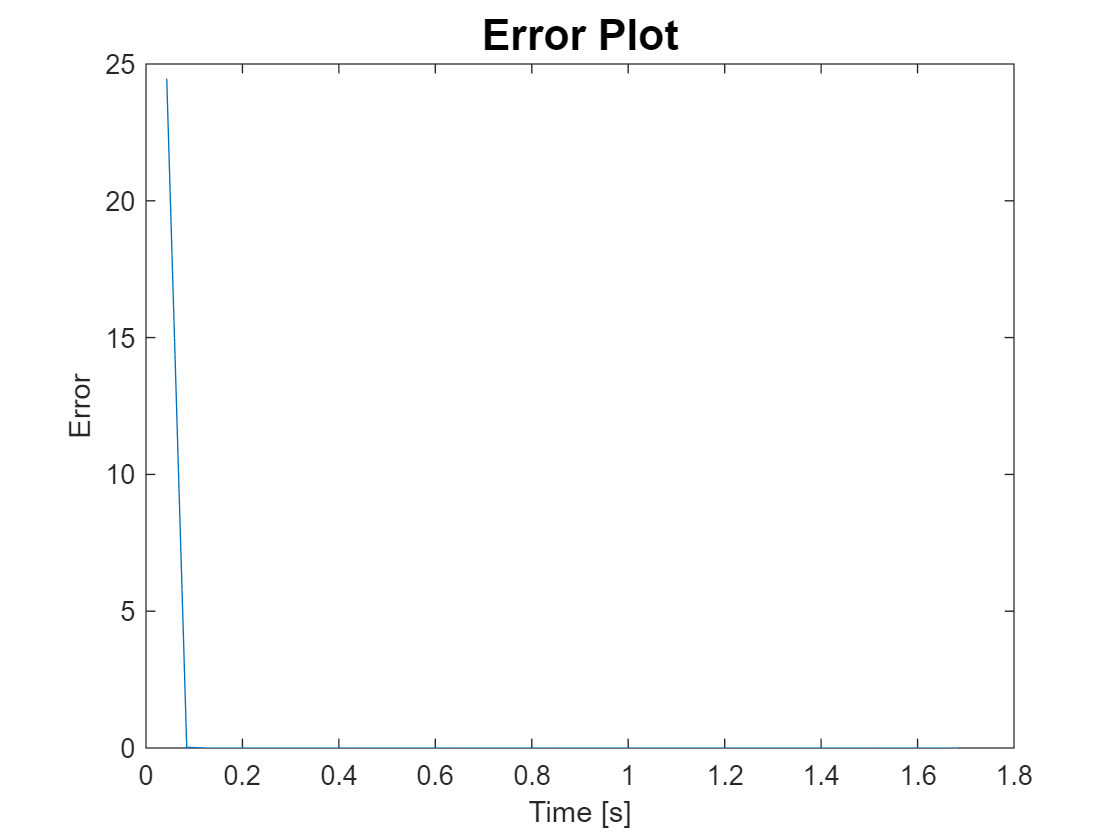

plot(timeCostseq, err_fseq)
title('Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

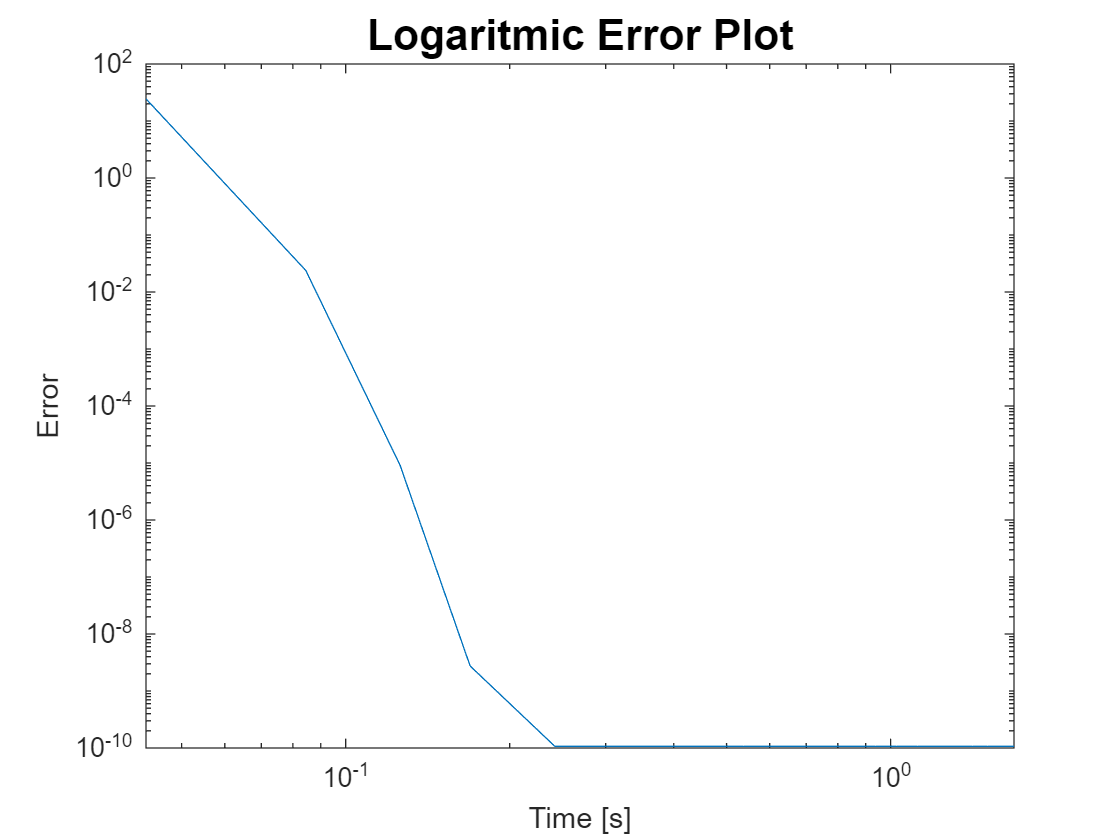

loglog(timeCostseq, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

## Modified Newton method - 10^4

### Parameters

kmax = 500;  % maximum number of iterations
step_k = 5;  % step between one iteration and the successive to memorize efficiently the orders fo convergence and the errors;
tolgrad = 1e-14;  % stopping criterion w.r.t. the norm of the gradient
c1 = 1e-4;  % factor of the Armijo condition
rho = 0.5;  % fixed factor used for reducing alpha0
btmax = 500;  % ﻿maximum number of steps for updating alpha
parameters = table(kmax, step_k, tolgrad, c1, rho, btmax)

parameters = 1×6 table
    kmax    step_k    tolgrad      c1      rho    btmax
    ____    ______    _______    ______    ___    _____

    500       5        1e-14     0.0001    0.5     500 


Hessf = @(x) 0;
FDgrad = 1;  % 'otherwise' case of "findiff_grad"
FDHess = 'Jc';
h = sqrt(eps)*norm(x0);
[xk, fk, gradfk_norm, k, big_k, err_fseq, ordconv_seq, ...
    totalTimeCost, timeCostseq] = modnewton_bcktrck(x0,x_sol,f,gradf,...
    Hessf,step_k,kmax,tolgrad,c1,rho,btmax, FDgrad, FDHess, h);

*** Tolerance is not respected ***

results_0 = table(xk, x_sol);
head(results_0, 8)

ans = 8×2 table
        xk         x_sol
    ___________    _____

     4.8633e-06      0  
    -4.8633e-07      0  
     5.3691e-21      0  
    -2.4136e-22      0  
     1.7039e-35      0  
    -1.7295e-35      0  
     2.3776e-49      0  
    -6.3049e-50      0  


tail(results_0, 8)

ans = 8×2 table
        xk         x_sol
    ___________    _____

    -2.7155e-49      0  
     2.3024e-50      0  
     5.0776e-37      0  
     -5.804e-37      0  
    -6.7353e-23      0  
     1.3337e-25      0  
    -3.5262e-06      0  
    -3.5262e-06      0  


gradfk_norm_x0 = norm(gradf(x0));
gradfk_norm_inf = norm(gradf(xk), "inf");
errf_final = err_fseq(end);
results_1 = table(fk, k, gradfk_norm_x0, gradfk_norm, gradfk_norm_inf, errf_final, totalTimeCost)

results_1 = 1×7 table
        fk        k     gradfk_norm_x0    gradfk_norm    gradfk_norm_inf    errf_final    totalTimeCost
    __________    __    ______________    ___________    _______________    __________    _____________

    9.6138e-21    55        7342.1        7.6376e-15       4.6011e-15       9.6138e-21       0.89102   


err_fseq = err_fseq';
ordconv_seq = ordconv_seq';
timeCostseq = timeCostseq';
results_2 = table(err_fseq, ordconv_seq, timeCostseq);
head(results_2, 8)

ans = 8×3 table
     err_fseq     ordconv_seq    timeCostseq
    __________    ___________    ___________

        134.28       1.2904        0.12637  
       0.93317        1.336        0.21768  
    0.00017731      0.95592        0.30226  
     1.643e-06      0.99975         0.3862  
    1.5217e-08            1        0.46569  
    1.4093e-10            1        0.53488  
    1.3053e-12            1        0.60368  
    1.2089e-14            1        0.67252  


tail(results_2, 8)

ans = 8×3 table
     err_fseq     ordconv_seq    timeCostseq
    __________    ___________    ___________

     1.643e-06      0.99975         0.3862  
    1.5217e-08            1        0.46569  
    1.4093e-10            1        0.53488  
    1.3053e-12            1        0.60368  
    1.2089e-14            1        0.67252  
    1.1197e-16            1        0.74322  
    1.0371e-18      0.99998         0.8194  
    9.6138e-21      0.99984        0.89102  


plot(1:big_k, err_fseq)
title('Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

loglog(1:big_k, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

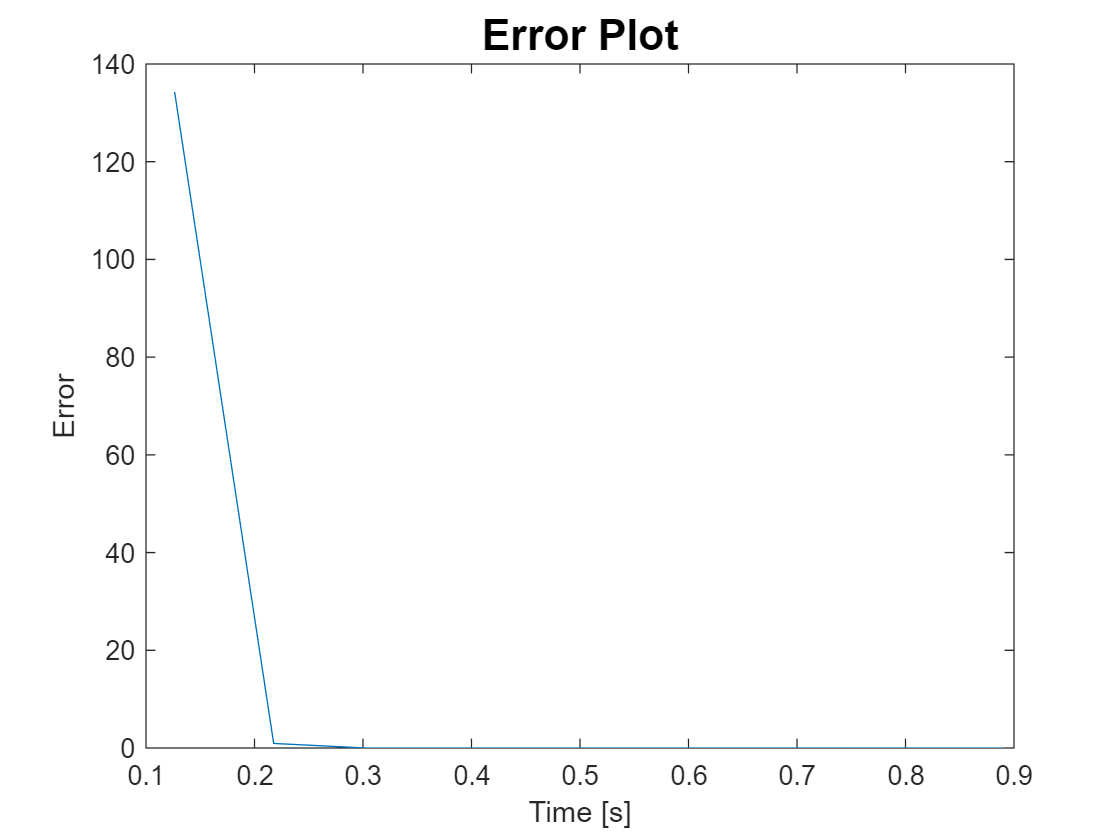

plot(timeCostseq, err_fseq)
title('Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

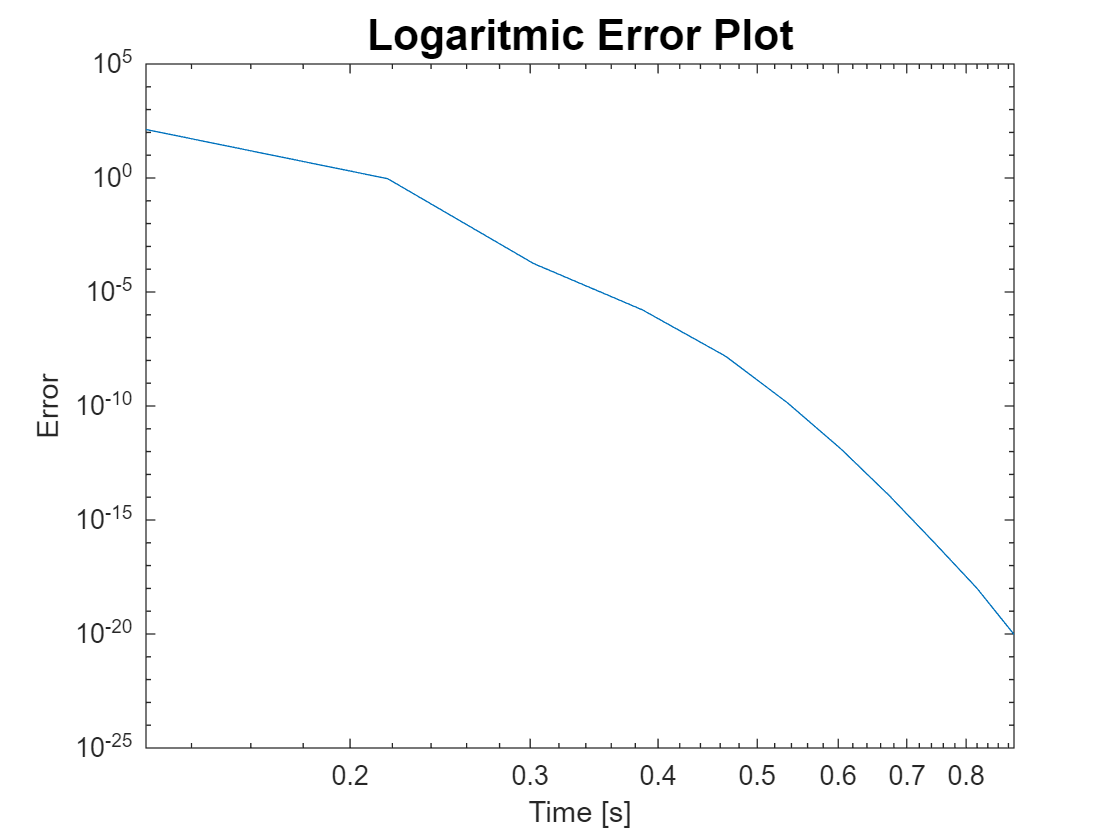

loglog(timeCostseq, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')